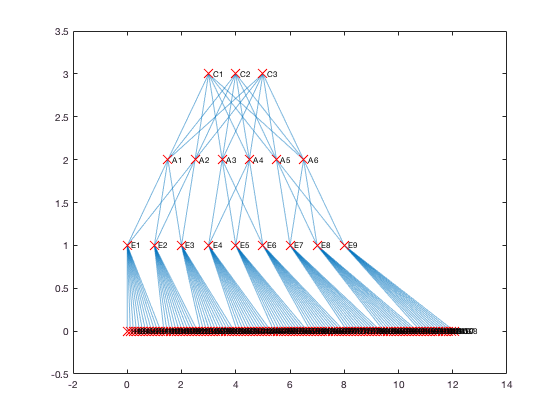

%da=4;
%dc=4;
k=6;
core=k/2;
aggregation=k;
TOR=k^2/4;%edges
agg_per_pod=2;
ecm=2*k;%O 20 o 40
flagit=false;
flaghosts=true;
agg_per_pod=2;

%Compute values for topology
assert(mod(k,2)==0,'Error, dc must be an even number.')
posnode=0;
it=0;
%core=da/2;
%aggregation=dc;
%TOR=da*dc/4;%edges
%ecm=2*dc;%O 20 o 40
variable_names_node_table = {'EndNodes';'Xpoint';'Ypoint';'Layer'};

%Compute values for plotting
differenceX=1;
startX=0; %Compute startX as the difference between total width and width of present layer divided by 2.
differenceY=1;
startY=4;
width=(TOR-1)*differenceX;
%if flaghosts
%    width=(ecm*TOR-1)*differenceX;
%else
%    width=(TOR-1)*differenceX;
%end

%Preallocation
if flagit
    it=1;
    posnode=it;
end
if ~flaghosts
    ecm=0;
end
h=aggregation+TOR+TOR*ecm+core+posnode;
endnodes = cell(h, 1);
Xpoint(h,1)=1;
Ypoint(h,1)=1;
layern(h,1)=1;
edges(it*core+aggregation*core+TOR*agg_per_pod+aggregation*ecm,2)=1;

%Internet layer
if flagit
    Xpoint(1,1)=width/2;
    Ypoint(1,1)=startY;
    layern(1)=0;
    endnodes{1}='IT';
end

%Core layer
startX=(width-(core-1)*differenceX)/2;
startY=startY-differenceY;
for i=1:core
    posnode=posnode+1;
    Ypoint(posnode,1)=startY;
    Xpoint(posnode,1)=startX+differenceX*(i-1);
    layern(posnode)=1;
    endnodes{posnode} = strcat('C', num2str(i));
    if flagit
    edges(i,1)= 1;
    edges(i,2)= i+1;
    end
end

%Aggregation layer
if flagit
    posedge=i;
else
    posedge=0;
end
posagg=posnode;
startY=startY-1;
startX=(width-(aggregation-1)*differenceX)/2;
for i=1:aggregation
    posnode=posnode+1;
    Ypoint(posnode,1)=startY;
    layern(posnode,1)=2;
    Xpoint(posnode,1)=startX+differenceX*(i-1);
    endnodes{posnode} = strcat('A', num2str(i));
    for j=it+1:core+it
        posedge=posedge+1;
        edges(posedge,1)=posnode;
        edges(posedge,2)= j;
    end
end

%Edge layer
startY=startY-1;
startX=(width-(TOR-1)*differenceX)/2;
countpod=1;
edge_per_pod=TOR/(aggregation/agg_per_pod);
for i=1:TOR
    posnode=posnode+1;
    Ypoint(posnode,1)=startY;
    layern(posnode,1)=3;
    Xpoint(posnode,1)=startX+differenceX*(i-1);
    endnodes{posnode} = strcat('E', num2str(i));
    if i>countpod*edge_per_pod
        countpod=countpod+1;
    end
    for j=1:agg_per_pod
        posedge=posedge+1;
        edges(posedge,1)=posnode;
        edges(posedge,2)= posagg+j+(countpod-1)*agg_per_pod;
    end
end
%Host layer
if flaghosts
    posagg=posagg+aggregation;
    differenceX=width/(ecm*TOR-1);
    startY=startY-1;
    posnode1=posnode;
    count=1;
    count2=1;
    for j=1:TOR
        addj=posnode1+(count2-1)*ecm;
        for i=1:ecm
            posnode=posnode+1;
            Ypoint(posnode,1)=startY;
            layern(posnode,1)=4;
            Xpoint(posnode,1)=startX+differenceX*(count-1);
            endnodes{posnode} = strcat('H', num2str(count));
            posedge=posedge+1;
            edges(posedge,1)=posagg+j;
            edges(posedge,2)=addj+i;
            count=count+1;
        end
        count2=count2+1;
    end
end

layer=categorical(layern,0:4,{'internet' 'core' 'aggregation' 'edge' 'host'});
NodeTable=table(endnodes,Xpoint,Ypoint,layer,'VariableNames',variable_names_node_table);
EdgeTable=table(edges,'VariableNames',{'EndNodes'});
G=graph(EdgeTable,NodeTable);
plotGraphtopology(G);